clearvars

addpath('Complex_Wave_ISM/');
addpath('Least_Mean_Square/');
addpath('Complex_Wave_ISM/ISM/');

## Active Noise Control using LMS

In the following we will implement an active noise control system using the least-mean-square algorithm to cancel out the noise source and the image source method to simulate the 3d-spaces reverberation.

We will start with very simple setting and build our way up to a realistic environment.

### Image order 0 - 1 error microphone - 1 noise source - 1 output source

We start in an open 3d space (no room reflections).

#### Initial parameter values

% -------------------------
% --------- Grid ----------
dimension = [10,10,10]; % Room dimensions (x,y,z)
spacing = 1; % (m) Spacing between each point of the grid
Nt = 0.05; % Number of timesteps
dt = 0.00001; % (s) Size of timesteps
t = 0:dt:Nt; % Time array.
% -------------------------
% ------ Positions --------
p_source = [5,0,0]; % (x,y,t) Source coordinates
p_receiver = [0,0,0]; % (x,y,z) Receiver coordinates
% -------------------------
% ---- Wave Equation ------
c = 343; % (m/s) Speed of sound
f = 1500; % Signal frequency in Hz
alpha = [0 0 0 0 0 0]; % Absorption coefficient
U0 = 0.001; % Radial velocity
a = 1; % Radius of emitting sphere
Q = 4*pi*a^2*U0; % Source strength
rho = 1.125; % Density of air
% -------------------------
% --------- IMS -----------
image_order = 0;

The receiver is located in the origin, the noise source at the Point (5,0,0) - 5m away from the receiver. The noise signal is a simple sine wave with a frequency of 150Hz.

The signal measured at the receiver would then be the following:

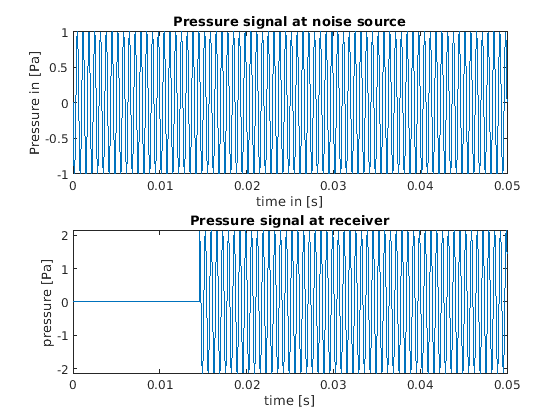

[in_p, out_p] = old_image_source_pressure_wave(p_source,p_receiver,dimension,t,spacing,c,f,Q,rho,image_order,alpha,0,0);
subplot(211);
plot(t,in_p);
xlabel("time in [s]");
ylabel("Pressure in [Pa]");
title("Pressure signal at noise source");
subplot(212);
plot(t,out_p);
xlabel("time [s]");
ylabel("pressure [Pa]");
title("Pressure signal at receiver");

### Primary source - shifted source

To test the principle of active noise control we will place a second noise source at equal distance from the receiver, however this noise source will emmit a phase shifted sine wave.

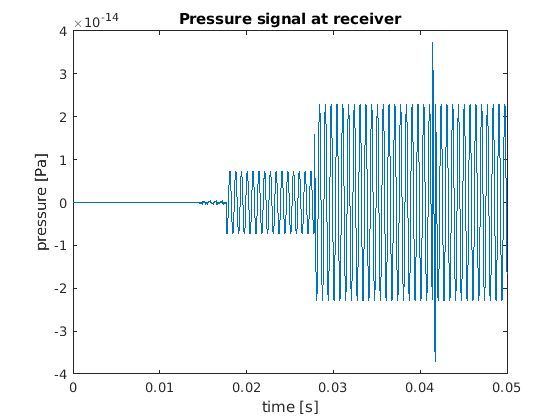

shift = [0,pi]; % Only the signal for the second source is shifted
p_source = [5,0,0;-5,0,0];
[in_p, out_p] = old_image_source_pressure_wave(p_source,p_receiver,dimension,t,spacing,c,f,Q,rho,image_order,alpha,shift,0);
figure;
plot(t,out_p(1,:));
xlabel("time [s]");
ylabel("pressure [Pa]");
title("Pressure signal at receiver");

As we can seen the signal reaching the receiver is greatly reduces (10e-14).

### Complex source signal

A typical noise source usualy does not consist of only one pure sine wave, but is made up of many. As we consider our system to be linear, we can decompose a complex source signal its basic sine waves, compute output pressure using the image_source_method for each sine wave, and add up the resulting output pressure waves to obtain the output pressure of the complex wave.

We therefore implement a function **decompose_wave** which takes a complex wave as input and outputs a matric of sine waves.

Ls = 5000;% Signal length
Fs = 1000;% Sampling frequency
Ts = 1/Fs;% Sampling period
t = (0:Ls-1)*Ts;        % Time vector
thresh = 0.1; % Threshold filtering the weakly represented sine waves
wave = sin(2*pi*50*t) + 0.5*sin(2*pi*25*t) + 0.1*sin(2*pi*22*t); % complex signal
[sw_freq,~,sine_waves] = decompose_wave(wave,t,Fs,Ts,thresh);

This signal is made out of 3 sine waves. When feeding it into the decompose_wave function we expect 3 seperate sine waves to be returned that when added up return the original source signal.

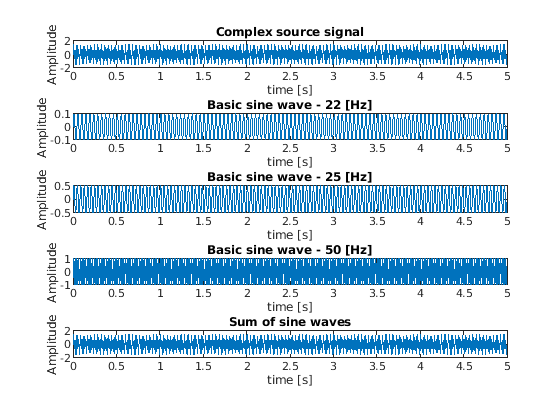

n = size(sine_waves,1);
figure;
subplot(n+2,1,1)
plot(t, wave);
title("Complex source signal");
xlabel("time [s]");
ylabel("Amplitude");
for i=1:n
    subplot(n+2,1,i+1);
    plot(t, sine_waves(i,:));
    title("Basic sine wave - " + sw_freq(i) + " [Hz]");
    xlabel("time [s]");
    ylabel("Amplitude");
end
subplot(n+2,1,n+2)
plot(t,sum(sine_waves));
title("Sum of sine waves");
xlabel("time [s]");
ylabel("Amplitude");

### Complex source signal ISM

We now need a function that takes in a complex wave function and implements the image source method for each fundamental sine waves and sums up the resulting output pressures.

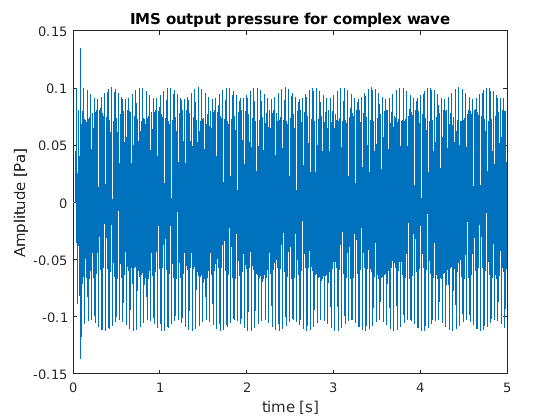

image_order = 2;
p_source = [20,0,0];
p_receiver = [0,0,0];
out_p = complex_wave_ism(wave,p_source,p_receiver,dimension,t,Fs,Ts,thresh,spacing,c,Q,rho,image_order,alpha,0);
figure;
plot(t,out_p);
title("IMS output pressure for complex wave");
xlabel("time [s]");
ylabel("Amplitude [Pa]");

### LMS test

We feed the lms function with sine wave as input signal and null wave as a reference signal. We expect the lms filter to output a phase shifted sine wave

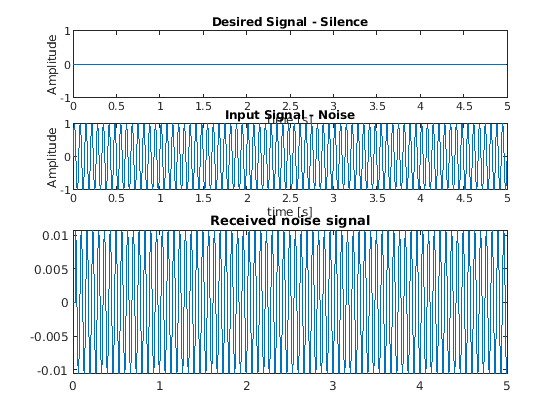

in_sig = sin(2*pi*15*t);
ref_sig = 0*t;
mu = 0.0001; % Step size
M = 100; % Filter length
[e,y] = lms(mu,M,in_sig,ref_sig);
subplot(4,1,1);
plot(t,ref_sig);
title("Desired Signal - Silence");xlabel("time [s]");ylabel("Amplitude");
subplot(4,1,2);
plot(t,in_sig);
title("Input Signal - Noise");xlabel("time [s]");ylabel("Amplitude");

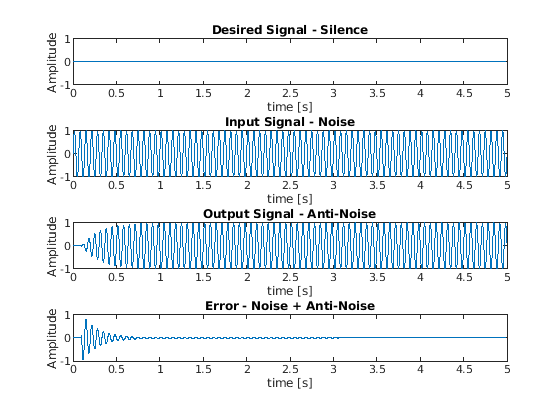

subplot(4,1,3);
plot(t,y);
title("Output Signal - Anti-Noise");xlabel("time [s]");ylabel("Amplitude");
subplot(4,1,4);
plot(t,e);
title("Error - Noise + Anti-Noise");xlabel("time [s]");ylabel("Amplitude");

For this simple example the lms filter seems to work. The output sine wave is infact phase shifted by 180° and the error signal (the sum of input and output wave / noise and anti-noise) converges to 0.

### LMS using IMS

The previous example expected the output signal to be added onto the noise signal directly at the error microphone. As the secondary (anti-noise) source is not located directly at the error microphone, the image-source method has to be applied to compute the new input signal at each consecutive step.

### Decompose lms output signal

We want do decompose the previous lms output signal to get an idea of this signal will be processed by the image source method.

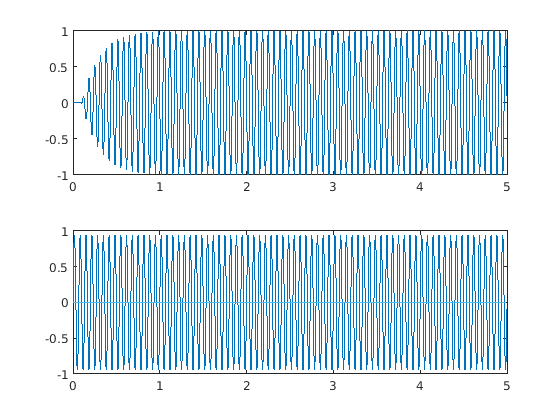

figure;
subplot(211)
plot(t,y);
[sine_f,f_mag,sine_waves] = decompose_wave(y,t,Fs,Ts,0.00001);
subplot(212)
plot(t,sine_waves)

### LMS using IMS

The previous example expected the output signal to be added onto the noise signal directly at the error microphone. As the secondary (anti-noise) source is not located directly at the error microphone, the image-source method has to be applied to compute the new input signal at each consecutive step.

image_order = 0;
mu = 0.1

mu = 0.1000

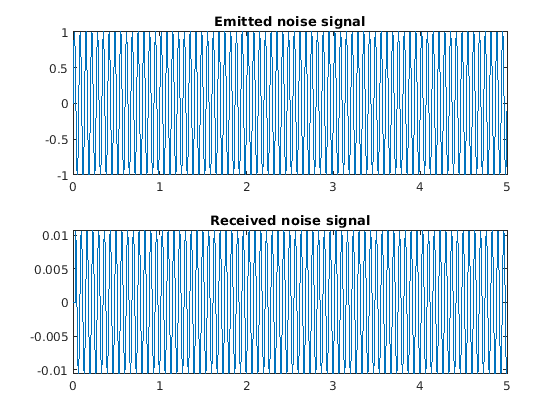

R = [0,0,0]; % Error microphone position
S1 = [10,0,0]; % Primary source - Noise
S2 = [5,5,0]; % Secondary source - Anti-Noise
[e,y]=new_lms(mu,M,in_sig,ref_sig,S1,S2,R,dimension,t,Fs,Ts,0.001,spacing,c,Q,rho,image_order,alpha,0);

figure;
subplot(2,1,1);
plot(t,e);
subplot(2,1,2);
plot(t,y);

figure;
subplot(211)
plot(t,y);
[sine_f,f_mag,sine_waves] = decompose_wave(y,t,Fs,Ts,0.00001);
subplot(212)
plot(t,sine_waves)